clear all; close all; clc
data = [];
[file, path, filterindex] = ...
    uigetfile('*.rhd', 'Select an RHD2000 Data File', 'MultiSelect', 'on');
for i = 1:length(file)
    read_Intan_RHD2000_file(file{i},path)
    data = [data, amplifier_data]; clear amplifier_data;
    clc
end

Reading Intan Technologies RHD2000 Data File, Version 1.5

Found 128 amplifier channels.
Found 6 auxiliary input channels.
Found 2 supply voltage channels.
Found 0 board ADC channels.
Found 0 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 42.588 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Applying notch filter...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Done!  Elapsed time: 2.4 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.


Reading Intan Technologies RHD2000 Data File, Version 1.5

Found 128 amplifier channels.
Found 6 auxiliary input channels.
Found 

clear y s f t p power freq
for ch = 1: 128
    temp_1 = decimate(data(ch,:),5,4);
    temp_2 = decimate(temp_1,5,4);
    y(ch,:) = decimate(temp_2,4,4);

    [s(:,:,ch),f{ch},t{ch},p(:,:,ch)] = spectrogram(y(ch,:),1000,200,[],200,'yaxis');

    [power(ch,:),freq(ch,:)] = pspectrum(y(ch,:),200);
    ch
end

ch = 1

ch = 2

ch = 3

ch = 4

ch = 5

ch = 6

ch = 7

ch = 8

ch = 9

ch = 10

ch = 11

ch = 12

ch = 13

ch = 14

ch = 15

ch = 16

ch = 17

ch = 18

ch = 19

ch = 20

ch = 21

ch = 22

ch = 23

ch = 24

ch = 25

ch = 26

ch = 27

ch = 28

ch = 29

ch = 30

ch = 31

ch = 32

ch = 33

ch = 34

ch = 35

ch = 36

ch = 37

ch = 38

ch = 39

ch = 40

ch = 41

ch = 42

ch = 43

ch = 44

ch = 45

ch = 46

ch = 47

ch = 48

ch = 49

ch = 50

ch = 51

ch = 52

ch = 53

ch = 54

ch = 55

ch = 56

ch = 57

ch = 58

ch = 59

ch = 60

ch = 61

ch = 62

ch = 63

ch = 64

ch = 65

ch = 66

ch = 67

ch = 68

ch = 69

ch = 70

ch = 71

ch = 72

ch = 73

ch = 74

ch = 75

ch = 76

ch = 77

ch = 78

ch = 79

ch = 80

ch = 81

ch = 82

ch = 83

ch = 84

ch = 85

ch = 86

ch = 87

ch = 88

ch = 89

ch = 90

ch = 91

ch = 92

ch = 93

ch = 94

ch = 95

ch = 96

ch = 97

ch = 98

ch = 99

ch = 100

ch = 101

ch = 102

ch = 103

ch = 104

ch = 105

ch = 106

ch = 107

ch = 108

ch = 109

ch = 110

ch = 111

ch = 112

ch = 113

ch = 114

ch = 115

ch = 116

ch = 117

ch = 118

ch = 119

ch = 120

ch = 121

ch = 122

ch = 123

ch = 124

ch = 125

ch = 126

ch = 127

ch = 128

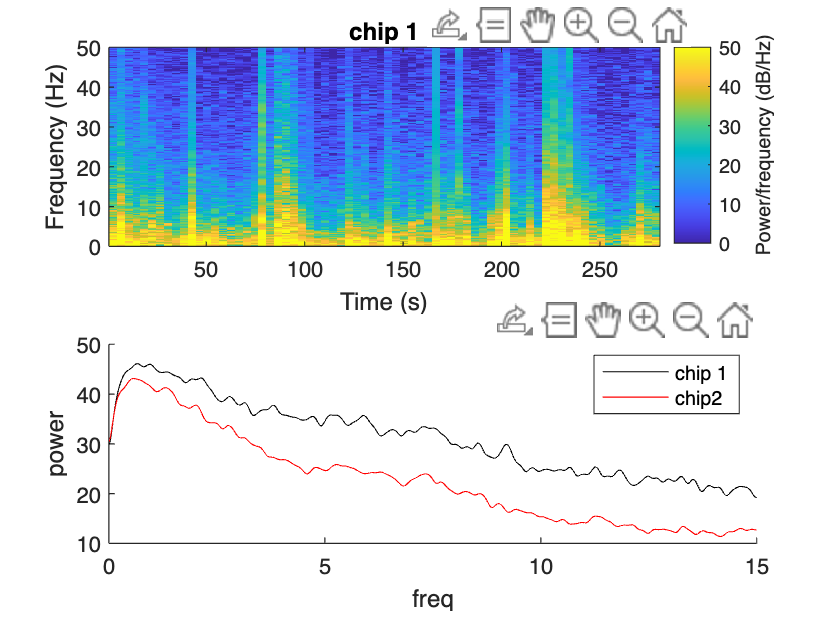

mean_p_chip1 = mean(p(:,:,1:64),3);
mean_p_chip2 = mean(p(:,:,65:128),3);

mean_power_chip1 = mean(10*log10(power(1:64,:)),1);
mean_power_chip2 = mean(10*log10(power(65:128,:)),1);

figure(1);
subplot(2,1,1);
imagesc(t{1}, f{1}, 10*log10(mean_p_chip1+eps)) % add eps like pspectrogram does
hold on;
axis xy
ylabel('Frequency (Hz)')
xlabel('Time (s)')
h = colorbar;
h.Label.String = 'Power/frequency (dB/Hz)';
axis tight
ylim([0 50]);
caxis([0 50])
hold off
title('chip 1')

subplot(2,1,2);
hold on
imagesc(t{1}, f{1}, 10*log10(mean_p_chip2+eps)) % add eps like pspectrogram does
axis xy
ylabel('Frequency (Hz)')
xlabel('Time (s)')
h = colorbar;
h.Label.String = 'Power/frequency (dB/Hz)';
axis tight
ylim([0 50]);
caxis([0 50])
hold off
title('chip 2')

[~,ind] = (min(abs(freq(1,:)-15)));
low_freq = 1:ind;
figure(2)
plot(freq(1,low_freq),mean_power_chip1(low_freq),'k')
hold on
plot(freq(1,low_freq),mean_power_chip2(low_freq),'r')
hold off
box off
ylabel('power')
xlabel('freq')
legend('chip 1','chip2')

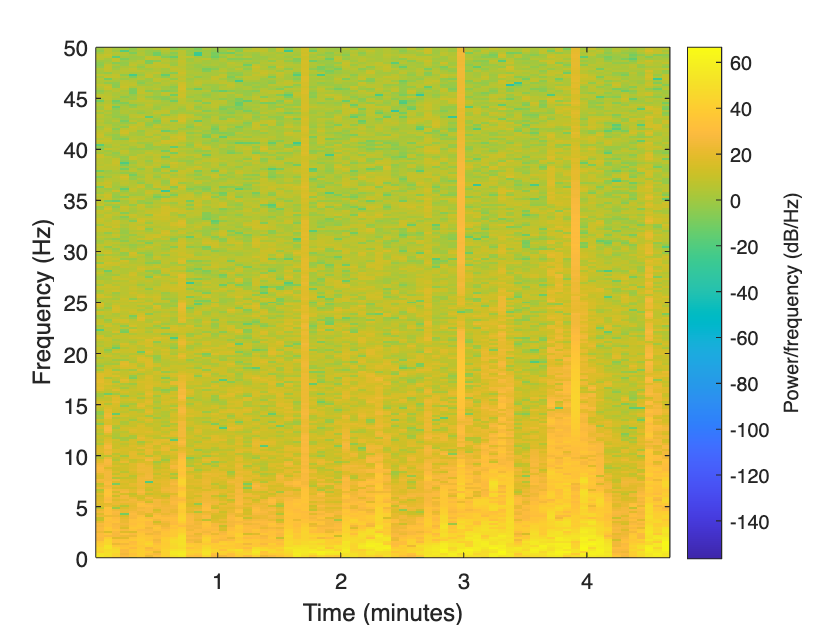

figure();
spectrogram(y(70,:),1000,200,[],200,'yaxis')
ylim([0 50]);